# Magnetic Resonance Principles

This tutorial explains some of the basic principles of magnetic resonance signals. The principles are illustrated for signals derived from a bulk substance, such as a beaker of water. Various terms used to describe the MR principles are introduced

- Spins

- parallel/anti-parallel

- Boltzman distribution

- T1 (spin-lattice or longitudinal relaxation), T2 (spin-spin, or transverse relaxation) 

- The concept of signal contrast is introduced. 

The next tutorial, tls_mri02Imaging, takes up the topic of how to make images that measure these tissue properties in a non-uniform volume.

As the first tutorial in the series, we go slowly to give you the opportunity to examine basic Matlab commands.

There are questions interspersed throughout this tutorial.  Some of them will be on the homework, and others are included  so you can check whether you understand the ideas.  Feel free to talk about these questions in the online sessions.

## **REFERENCES FOR THIS TUTORIAL**

**Huettel et al. 3rd edition** Chapters 1-3 (mainly Chapter 3). 

Note: 1st v. 2nd v. 3rd edition of **Huettel book**: The second and third editions are quite similar, especially in the earlier chapters. References followed by "ii" are 2nd edition, "i" first edition. Hence p. 51i, 60ii means p 51 in the first edition, p 60 in the second. And so on.

[John Hornak online MRI book ](http://www.cis.rit.edu/htbooks/mri/index.html.)is a good reference, especially [Chapter 3](http://www.cis.rit.edu/htbooks/mri/inside.htm%3E)

**McRobbie et al, MRI, From Picture to Proton**, Chapter 8 is a good reference.

## Psych 204a: Basic MR principles

- Author: Wandell

- Date:  **2003.15.04**

- Duration: 90 minutes

**Checked: **

- 2007.XX.XX: Rory Sayres

- 2009.22.09: Jon Winawer

- 2009.18.10 Jon Winawer

- 2011.09.22 Brian Wandell

- 2018.01.05 Brian Wandell

- 2021.01.05 Insub Kim 

## Overview

The protons in your body, mostly part of the water molecules, can be likened to the Earth: the protons spin on an axis and have both a north and south pole.  Under normal circumstances, the orientation of the two poles is random.  But when protons are placed in an external magnetic field (when you put participants into the scanner), they tend to align parallel or anti-parallel to the orientation of the field.  The proportion of protons aligned with the field is calculated by **Boltzmann's formula**. The protons also spin (precess) around the direction of the magnetic field. The precession frequency, which also depends on the strength of the magnetic field.  This is the resonant frequency, or in MR we call it the **Larmor frequency**.

## Spins resonance frequency

When a substance is placed in a steady magnetic field, the spins (protons) precess at a frequency that is characteristic of the substance. For a beaker of water, the spins are hydrogen atoms.  We can compute the precession frequency from the following simple formula (Note the units - see chapter 3 and ca. p. 51i, 60ii for a discussion of precession). 

B0 = 1.5;     % Magnetic field strength (Tesla)
g = 42.58e+6; % Gyromagnetic constant for hydrogen (Hz / Tesla)
v = g*B0;     % The resonant (Larmor) frequency of hydrogen

% Ordinarily, the Larmor (resonant) frequency is expressed in Megahertz
% (millions of hertz)
fprintf('Hydrogen Larmor frequency\n %0.4f MHz at %.1f Tesla',...
    v/(10^6),B0);

Hydrogen Larmor frequency
 63.8700 MHz at 1.5 Tesla

## **Question 1**

What is the  Larmor frequency of hydrogen in a field at 3 Tesla?

% write your code and answer here 


## Spin Energy

The energy in a precessing spin is proportional to its resonant frequency, v (1/sec). The constant of proportionality between energy and frequency is a famous constant called **Planck's constant**. (Extra credit: Find out something interesting about Max Planck). Hence, the  energy in a hydrogen molecule in this magnetic field is

h = 6.626e-34; % Planck's constant (Joule-sec)
E = h*v;

## **Question 2**

What are the units of energy (E) in this formula?

## Boltzmann's formula 

At steady state, say when the subject enters the magnet and prior to any measurements, the spins (also called dipoles) align parallel or anti-parallel to the magnetic field. (The textbook illustrates this with a nice metaphor of gravity in Figure 3.7ii, 3,6i.) 

The energy difference between the parallel and anti-parallel states is proportional to the mean magnetic field. This is called the Zeeman effect (see Figure 3.8i, 3.9ii in the book). 

The proportion of dipoles aligned parallel (low energy) and anti-parallel (high energy) to the main field is described by the Boltzmann distribution. The formula that determines the fraction of dipoles in the low and high energy states is in Hornak (Chapter 2).

As the Boltzmann formula tell us (shown below), at a room temperture, there are slightly more number of spins in the **lower** energy level.

k = 1.3805e-23;      % Boltzmann's constant, J/Kelvin
T = 300;             % Degrees Kelvin at room temperature
dE = h * g * B0;     % Transition energy

% Boltzmann's formula, Hornak, Chapter 3; Huettel, p. 76ii
ratioHigh2Low = exp(-dE/(k*T));

% Under typical conditions the number of dipoles in the low and high energy
% states are very similar.
fprintf('Ratio of high (anti-parallel) to low (parallel) energy state dipoles:\n  %e',ratioHigh2Low)

Ratio of high (anti-parallel) to low (parallel) energy state dipoles:
  9.999898e-01

At low temperatures (near absolute zero), very few of the dipoles enter the high (anti-parallel) energy state. This is not important for us, but I find the numbers interesting.  In fact, I can see why people might want to work on low temperature physics for a while.

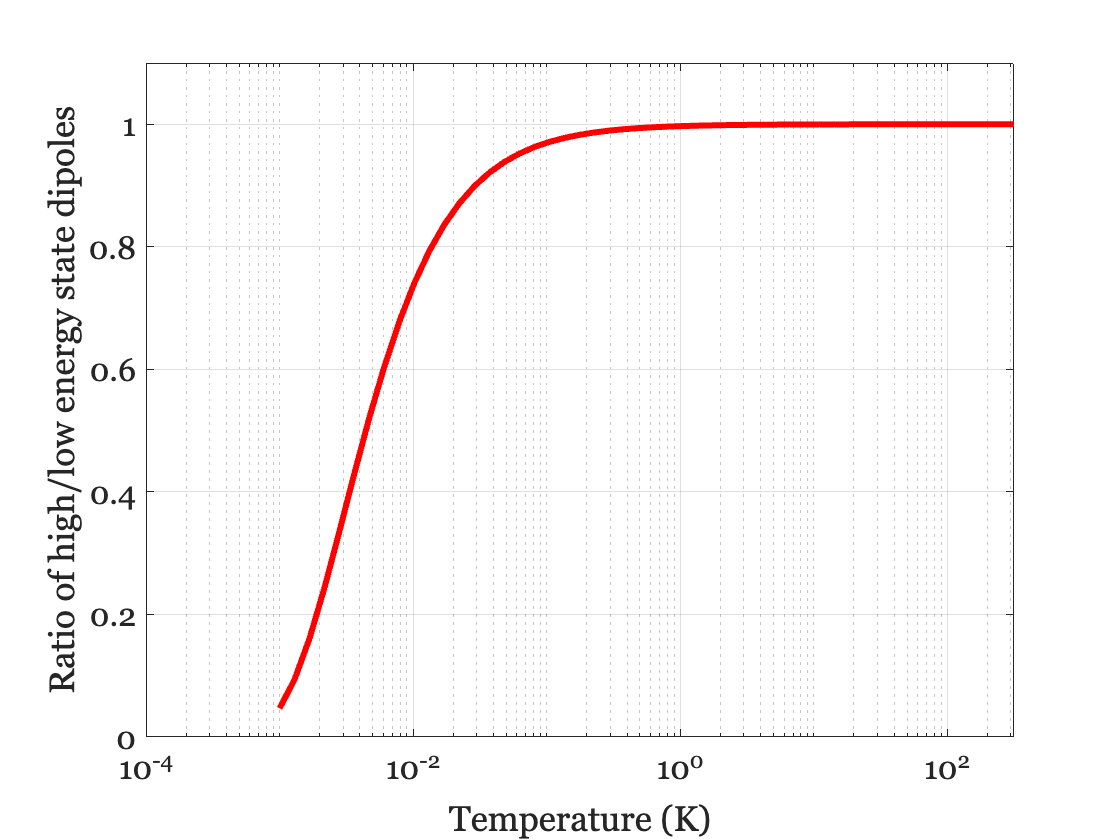

T = logspace(-3,2.5,50);
r = exp( -dE ./ (k*T));

figure;
semilogx(T,r,'LineWidth',3);
xlabel('Temperature (K)'); ylabel('Ratio of high/low energy state dipoles')
set(gca,'ylim',[-0 1.1]); grid on

## Question 3

- Where is human body temperature on the graph? 

- Given human body temperature, what is the ratio of high/low energy?

- Would the number change meaningfully if we cool the room by 10 C? 

% write your code and answer here 

## Net magnetization

The MR measurements that we obtain describe the **net magnetization** in the direction perpendicular to the main axis (B0 field). This direction is illustrated in the following figures. 

First, here is a 3D plot that shows the net magnetization as a red circle in the steady-state. The blue lines show the three axes.

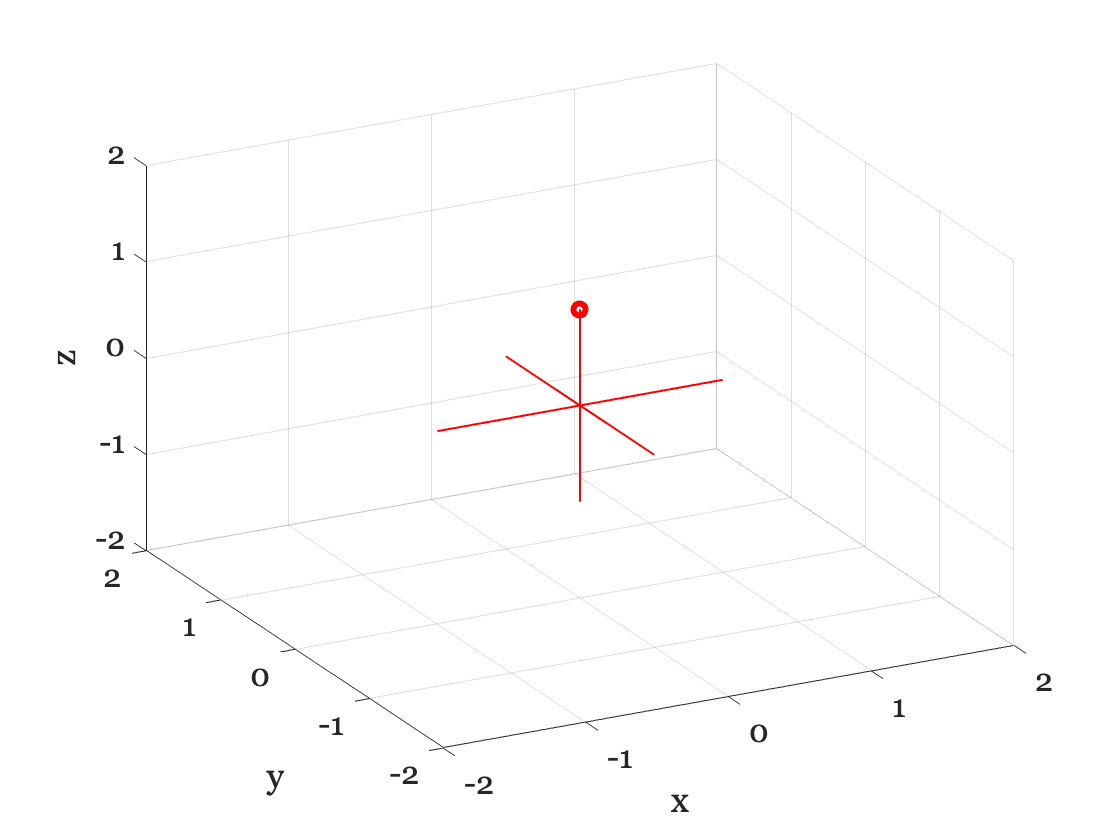

figure;
plot3(0,0,1,'ro','LineWidth',3)
set(gca,'xlim',[-2,2],'ylim',[-2 2],'zlim',[-2 2])

% showAxis
line([-1 1],[0 0],[0 0]);
line([0 0],[-1 1],[0 0]);
line([0 0],[0 0],[-1 1]);
grid on
xlabel('x'), ylabel('y'), zlabel('z')

% Set the azimuth and elevation of the view
AZ0 = 332.5; EL0 = 30; view(AZ0,EL0);

The size of the MR signal we measure depends on how far the net magnetization deviates from the main z-axis. We can see this deviation more easily by looking at the figure straight from the top. From this view, the point is at (0,0) in the (x,y) plane.

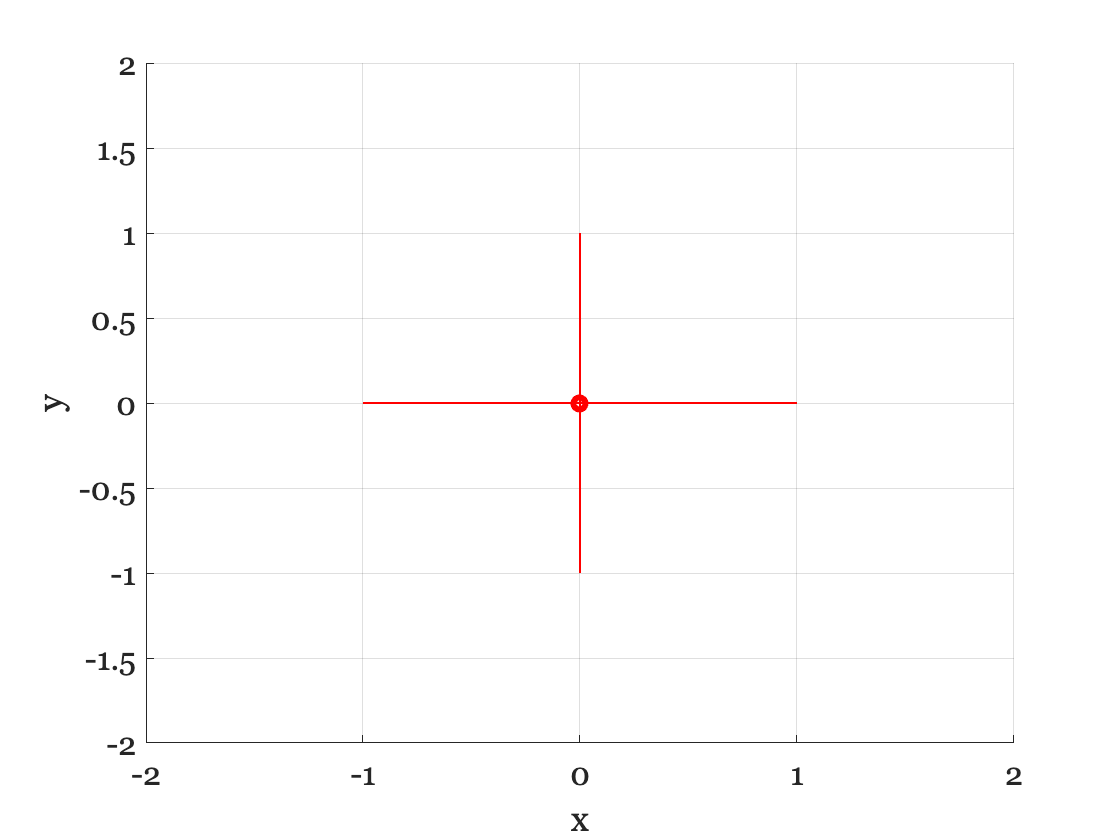

AZ1 = 0; EL1 = 90 ;  
view(AZ1,EL1)

Notice that from this view, looking down the z-axis, we see only the x- and y-axes. The net magnetization is at (0,0) so we will not see any signal. Now, let's put the picture back to the 3D view.

view(AZ0,EL0);

Suppose we excite the tissue and place the net magnetization along the x-axis (90 deg RF pulse). When we look from the top now, we see that there is a large magnetization component. The green point is removed from (0,0) and falls along the x-axis.

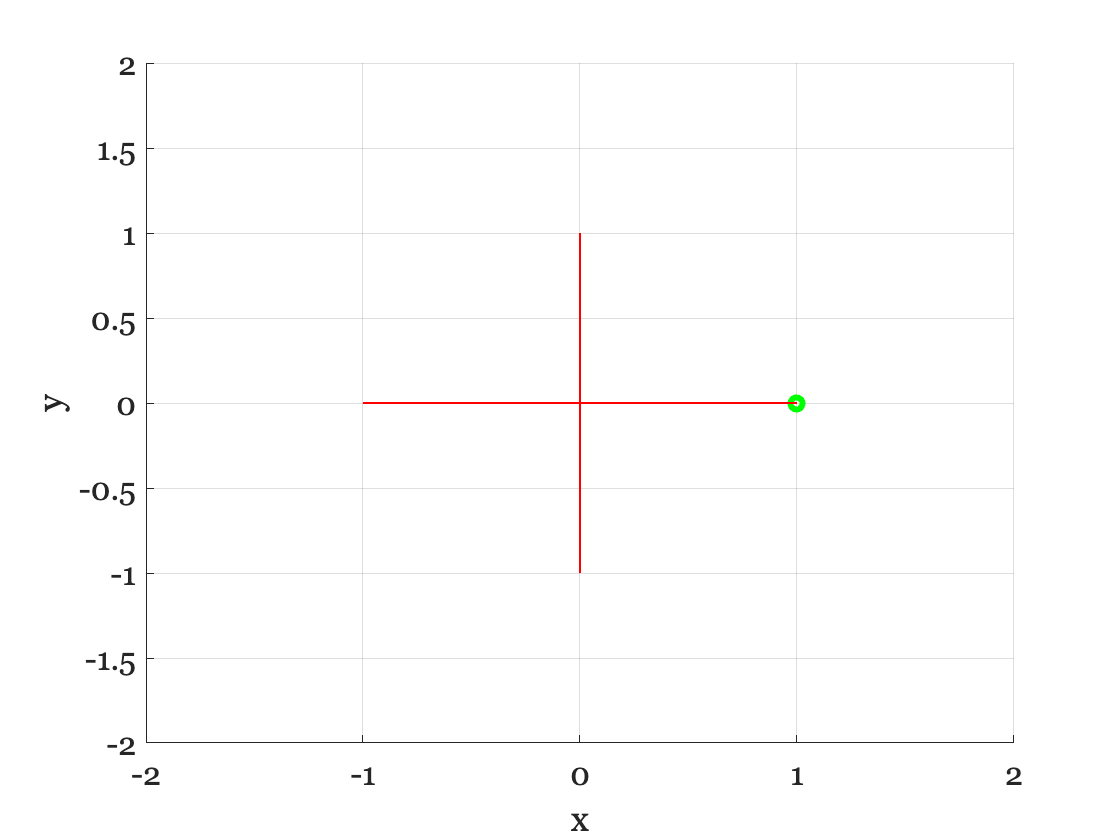

plot3(1,0,0,'go','LineWidth',3)
set(gca,'xlim',[-2,2],'ylim',[-2 2],'zlim',[-2 2]);
line([-1 1],[0 0],[0 0]);
line([0 0],[-1 1],[0 0]);
line([0 0],[0 0],[-1 1]);
grid on
xlabel('x'), ylabel('y'), zlabel('z')
AZ1 = 0; EL1 = 90 ;  view(AZ1,EL1)

When we change the net magnetization from the steady-state position (red circle) to the excited position (green circle), we are introducing a 90 deg rotation in the magnetization direction. This is usually called the flip angle. This is one of the parameters that you select when doing MR imaging.

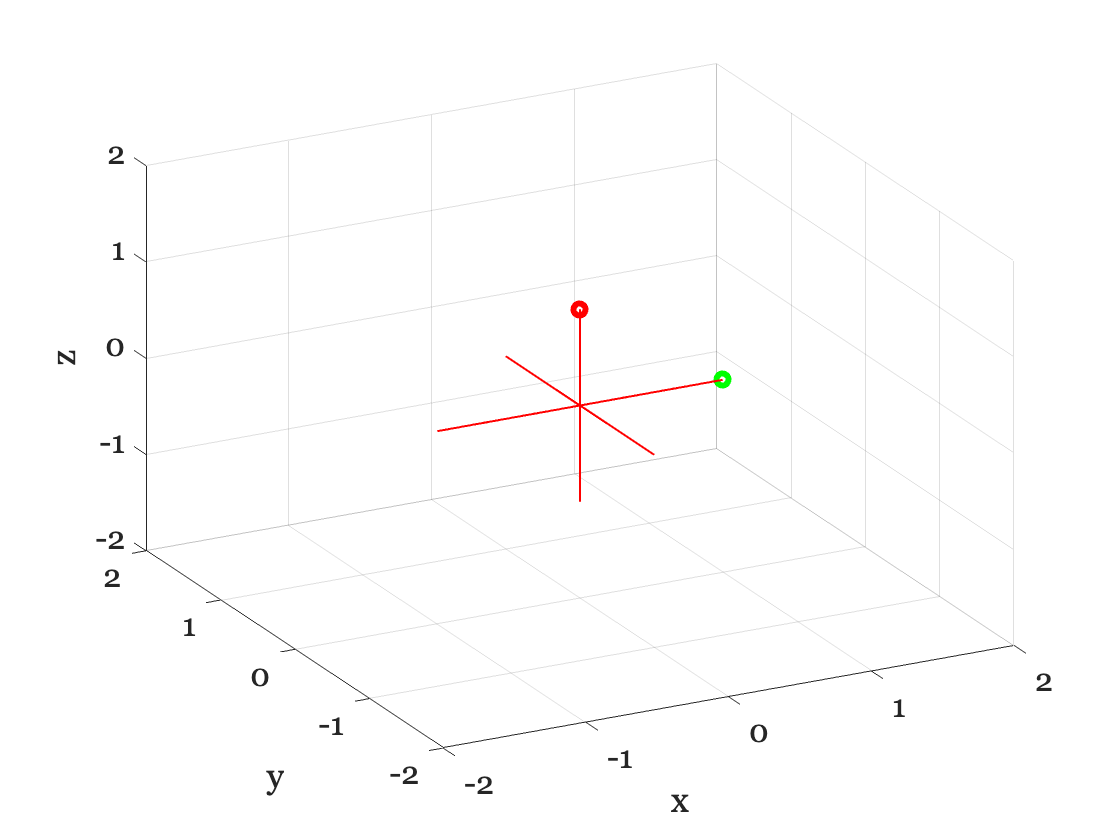

clf
plot3(0,0,1,'ro',1,0,0,'go','LineWidth',3)

% Show axis
set(gca,'xlim',[-2,2],'ylim',[-2 2],'zlim',[-2 2])
line([-1 1],[0 0],[0 0]);
line([0 0],[-1 1],[0 0]);
line([0 0],[0 0],[-1 1]);
grid on
xlabel('x'), ylabel('y'), zlabel('z')

% Set up viewing direction
AZ0 = 332.5; EL0 = 30; view(AZ0,EL0);

As the net magnetization returns to the steady-state position, the distance from the origin decreases, reducing the signal. This is illustrated by the collection of green points plotted here that illustrate the net magnetization rotating back towards the z-axis.

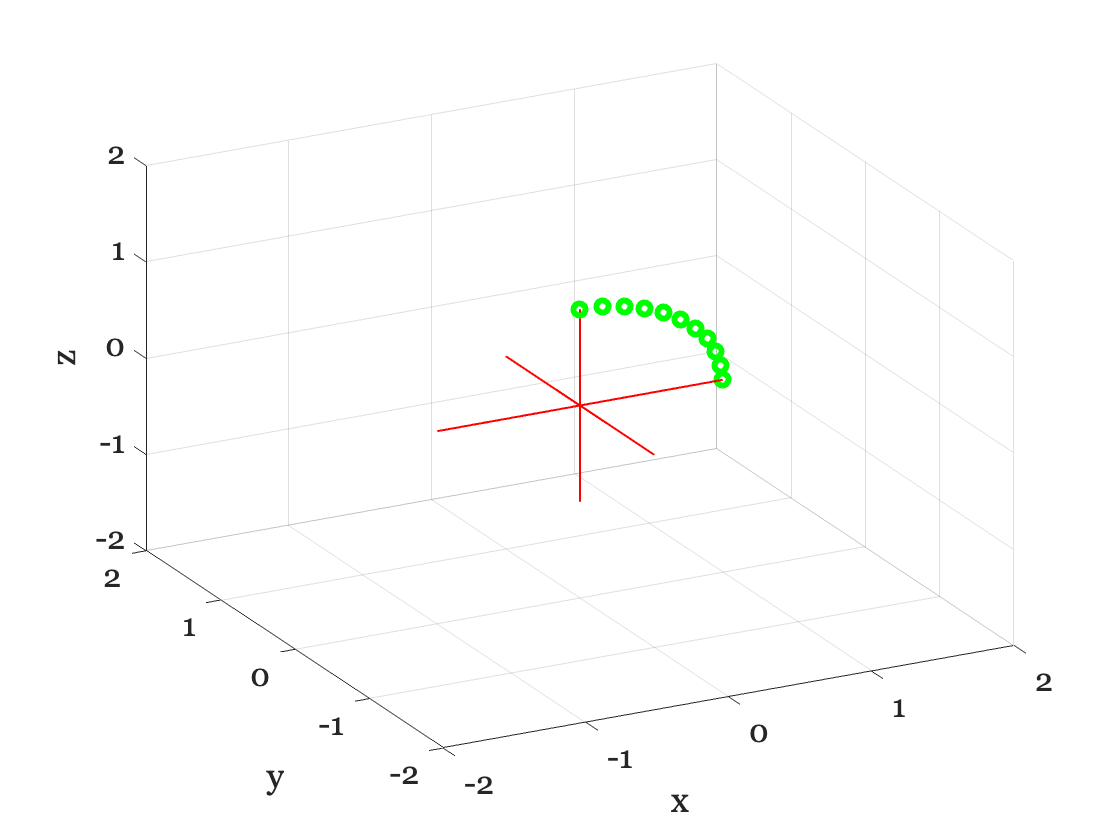

theta = (pi/2)*((0:10)/10);
x = cos(theta);  z = sin(theta);  y = zeros(size(x));
plot3(x,y,z,'go','LineWidth',3)
set(gca,'xlim',[-2,2],'ylim',[-2 2],'zlim',[-2 2])
line([-1 1],[0 0],[0 0]);
line([0 0],[-1 1],[0 0]);
line([0 0],[0 0],[-1 1]);
grid on
xlabel('x'), ylabel('y'), zlabel('z');
AZ0 = 332.5; EL0 = 30; view(AZ0,EL0);

When viewed from the top, you can see that the green points head back towards the origin.

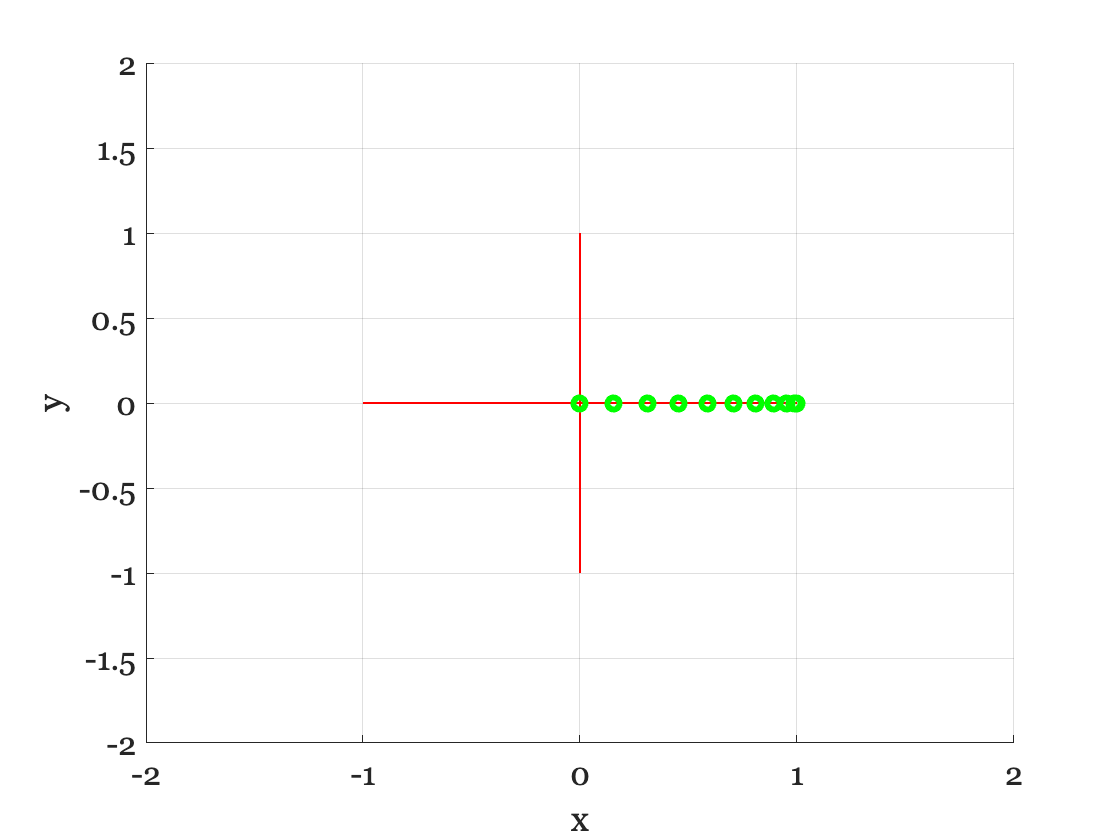

AZ1 = 0; EL1 = 90 ;  view(AZ1,EL1)

After receiving an excitation pulse, this component of the MR signal decays gradually over time. The spin-lattice decay has been measured and, in general, it follows an exponential decay rate.

Specifically, here is the rate of recovery of the T1 magnetization for hydrogen molecules in gray matter.

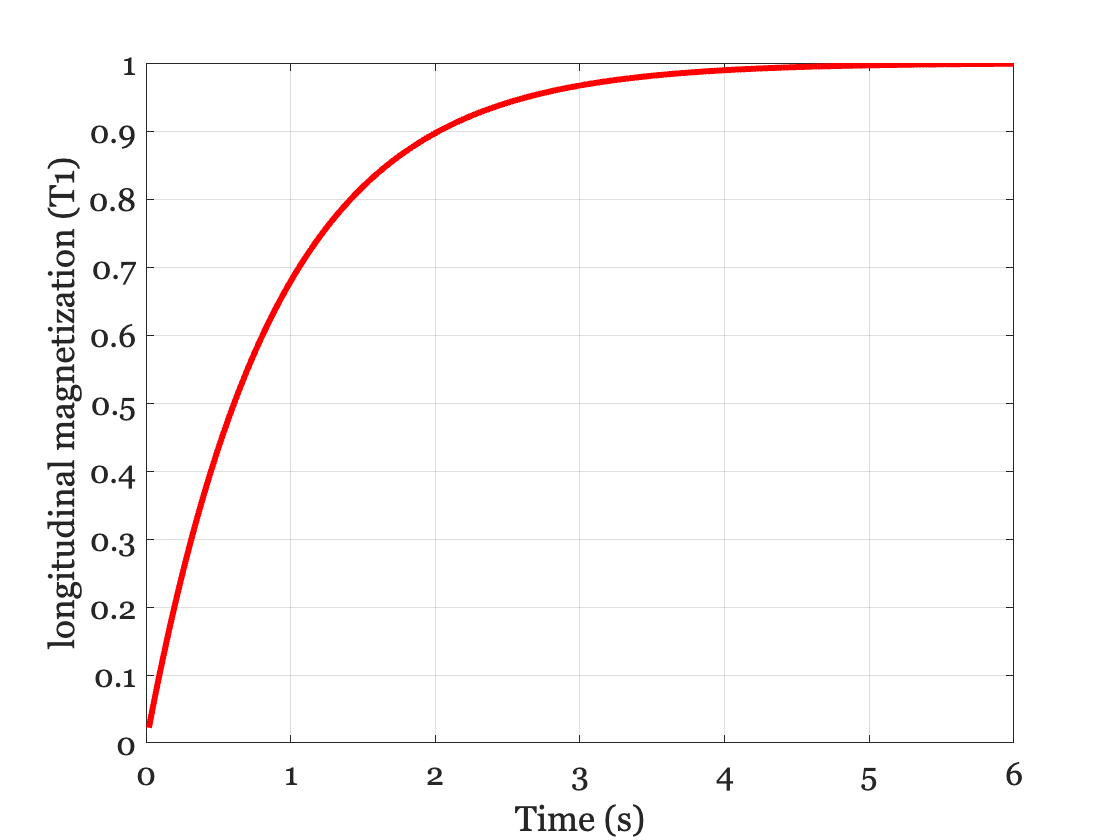

T1 = 0.88;          % Time constant units of S
t = (0.02:0.02:6);  % Time in seconds
Mo = 1;             % Set the net magnetization in the steady state to 1 and ignore.

% This is the exponential rate of recovery of the T1 magnetization, after
% it has been set to zero by flipping the net magnetization 90 degrees.
MzG = Mo *( 1 - exp(-t ./ T1) );

% Plotted is a graph we have the magnetization of gray matter as:
plot(t,MzG,'LineWidth',3);
xlabel('Time (s)'); ylabel('longitudinal magnetization (T1)'); grid on

The exponential time constant (recovery rates) for various brain tissues (summarized by the parameter T1 above) differs both with the material and with the level of the B0 field.The value T1 = 0.88 seconds above is typical of gray matter at 1.5T.

The T1 value for white matter is slightly smaller. Comparing the two we see that white matter recovers slightly faster (has a smaller T1):

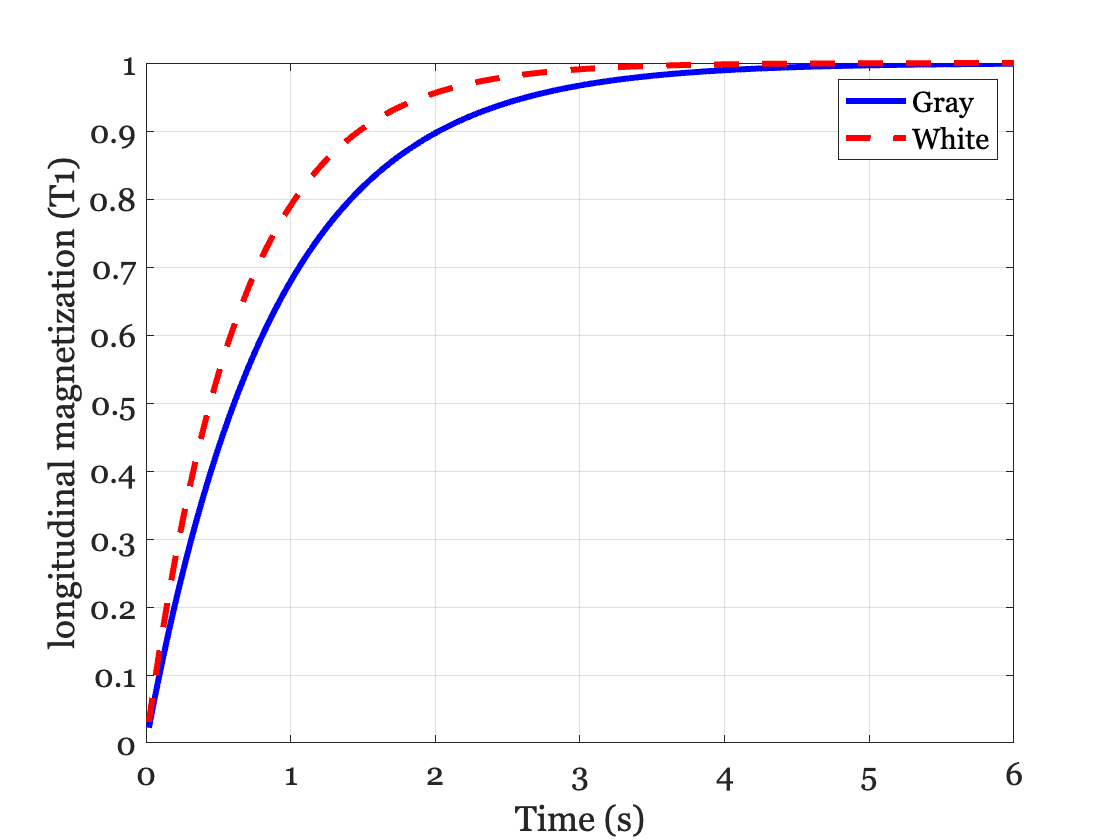

T1 = 0.64;
MzW = Mo *( 1 - exp(-t ./ T1) );
plot(t,MzG,'b-',t,MzW,'r--','LineWidth',3);
xlabel('Time (s)'); ylabel('longitudinal magnetization (T1)'); grid on
legend('Gray','White')

Notice that the time to recover all the way back to Mo is fairly long, on the order of 3-4 sec. This is a limitation in the speed of acquisition for T1 imaging.

The difference in the T1 component of the signal from gray matter and white matter changes over time. This difference is plotted in the next graph.

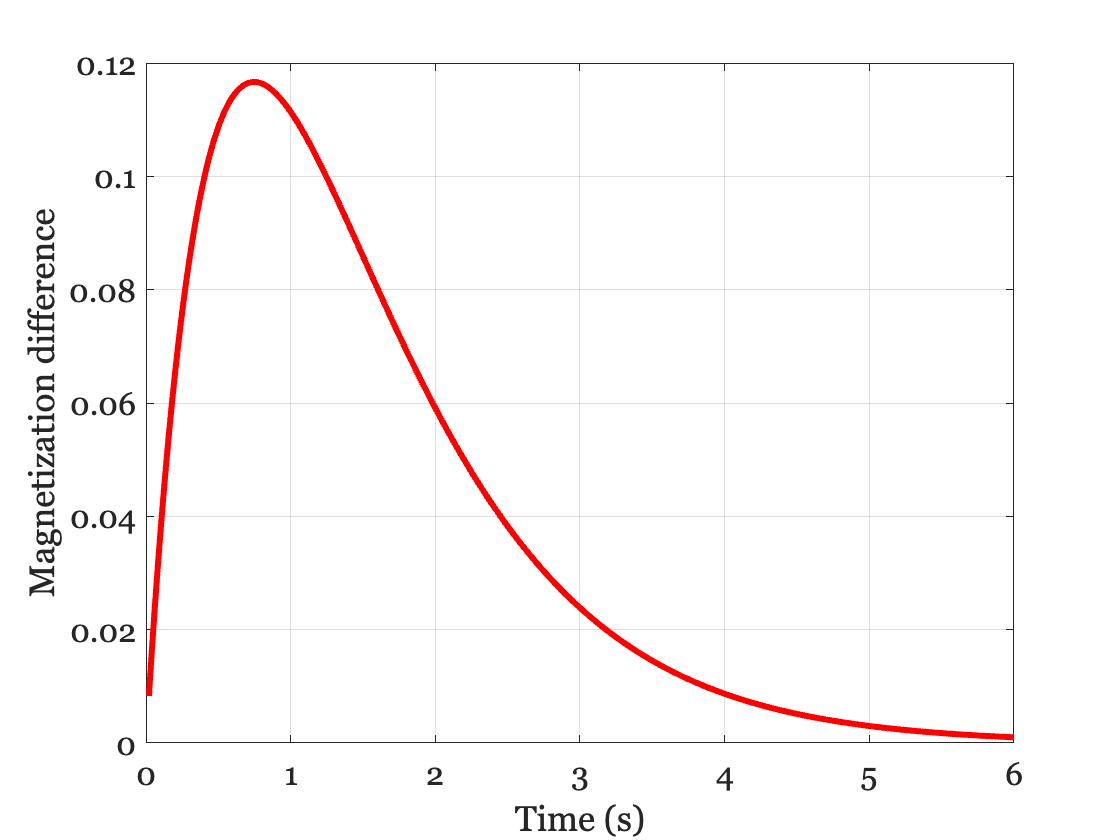

plot(t,abs(MzW - MzG),'LineWidth',3);
xlabel('Time (s)'); ylabel('Magnetization difference'); grid on

## Question 4

If you are seeking to make a measurement that optimizes the difference between these two materials, at what time would you measure the recovery of the T1 signal? 

% write your code and answer here 


## Tissue contrast

Suppose you take a picture of a piece of gray paper.  The whole image will simply be gray, without any pattern on it.  Kind of dull.  If we draw with a black pen on the page, however, some parts will be gray and others black.  The difference between the gray and black parts is called the image contrast.  Because there is a pattern on the page, we say the image has contrast.  The pattern may contain useful information.

If all the tissues in the brain had the same T1 value, then images of the brain based on T1 would be no more interesting than images of the gray paper.  In fact, different tissue types within the brain have a range of T1 values.  Some regions are brighter than the gray, and some are darker.  So when we measure the brain, we can create a picture with contrast.  Tissue contrast is an important part of making a useful MR image.  

The flexibility of MR methods allows us to create many types of contrast - as if drawings on the paper were made with a variety of colored pens.  Each type of contrast can potentially reveal different types of information.

Different types of brain tissue have different T1 values.  This enables us to make useful pictures (with contrast) of the brain. But remember the T1 value is a time constant.  So having different T1 values means that the signals we obtain vary over time.  How do we create these images from the time-varying signal?

We can visualize this difference as follows. Suppose that we have two beakers, adjacent to one another, containing materials with different T1 values. Suppose we make a pair of images in which the intensity of each image is set to the T1 value over time. What would the T1 images look like? 

The beakers start with the same, Mo, magnetization.

beaker1 = Mo*ones(32,32);
beaker2 = Mo*ones(32,32);

% They will have different T1 relaxation values
T1(1) = 0.64;       % T1 for white matter
T1(2) = 0.88;       % T1 for gray matter
mrvNewGraphWin;
movieT = (0.001:.1:4);   % We sample the movie at these times (in sec)

## Question 5

Look up the T1 value of cerebro-spinal fluid (CSF). Plot the T1 recovery of CSF. At what time you would measure to maximize the white/CSF contrast.

% write your code and answer here 


Here is a movie, slowed down, showing the relative intensities of the images over a 4 sec period, sampled every 100 ms. The frames are shown at 1/4 the real speed (i.e., every 100 ms). As you can see, if we make a picture of the net magnetization around 0.6-1.0 sec during the decay, there will be a good contrast difference between the gray and white matter. Measured earlier or later, the picture will have less contrast.

**Note: Movies don't play well inside this Live Code ... they should appear in an external window.**

mrvNewGraphWin;
colormap(gray(256));
for ii=1:length(movieT)
    img1 = beaker1*( 1 - exp(-movieT(ii) / T1(1)) );
    img2 = beaker2*( 1 - exp(-movieT(ii) / T1(2)) );
    img = [img1; img2];
    image(img*256); axis equal;
    drawnow; pause(0.1);
    text3 = text(40,32,sprintf('Time: %.2f sec',movieT(ii)));
end

As a preview of further work, later in the course, we should add just a little noise to the measurements. After all, all measurements have some noise. Let's look again. 

for ii=1:length(movieT)
    img1 = beaker1*( 1 - exp(-movieT(ii) / T1(1)) ) + randn(size(beaker1))*0.05;
    img2 = beaker2*( 1 - exp(-movieT(ii) / T1(2)) ) + randn(size(beaker1))*0.05;
    img = [img1; img2];
    image(img*256); axis equal
    drawnow; pause(.1);
    text3 = text(40,32,sprintf('Time: %.2f sec',movieT(ii)));
end

## Question 6

Instead of plotting the difference, plot the ratio of the levels, MzW and MzG. 

- When is the ratio the biggest?

- Why would we measure at a time when the difference, rather than ratio is biggest? 

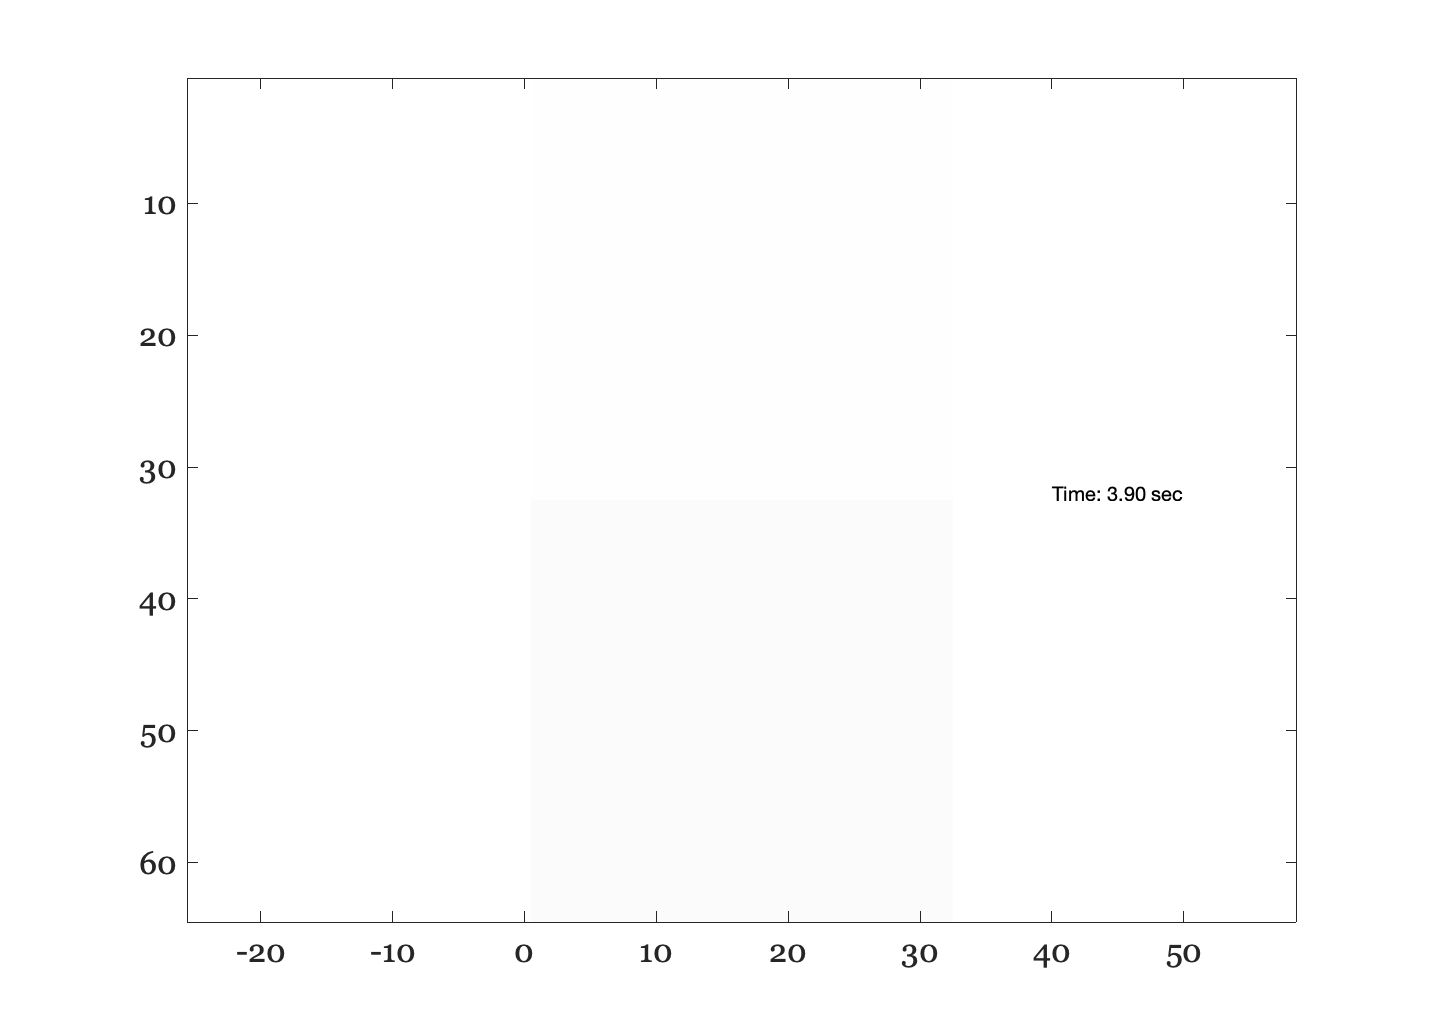

% write your code and answer here 


## T2 signals

There is a second physical mechanism, in addition to the spin-lattice measurement, that influences the MR signal. This second mechanism is called spin-spin interaction (transverse relaxation). This signaling mechanism is particularly important for functional magnetic resonance imaging and the BOLD signal.

In describing the T1 signal, we treated the MR signal as a single unified vector. In the example above, we explored what happens to the net magnetization of the MR signal when the vector is rotated 90 deg into the x-y plane.

But we omitted any discussion the fact that the dipoles are assumed to be continuously precessing around the main axis together, in unison. Perhaps in a perfectly homogeneous environment, these rotating dipoles would precess at the Larmor frequency in perfect synchronization and we could treat the single large vector as we have.

But in practice, the dipoles within a single voxel of a functional image each experience slightly different magnetic field environments. Consequently, they each have their own individual Larmor frequencies, proportional to the magnetic field that they experience. An important second mechanism of MR is a consequence of the fact that the individual dipoles each have their own local magnetic field and the synchrony soon dissipate.

Suppose we have a large sample of dipoles that are spinning together in perfect phase. We can specify their orientation as an angle in this plane, theta. Let's assume they all share a common angle

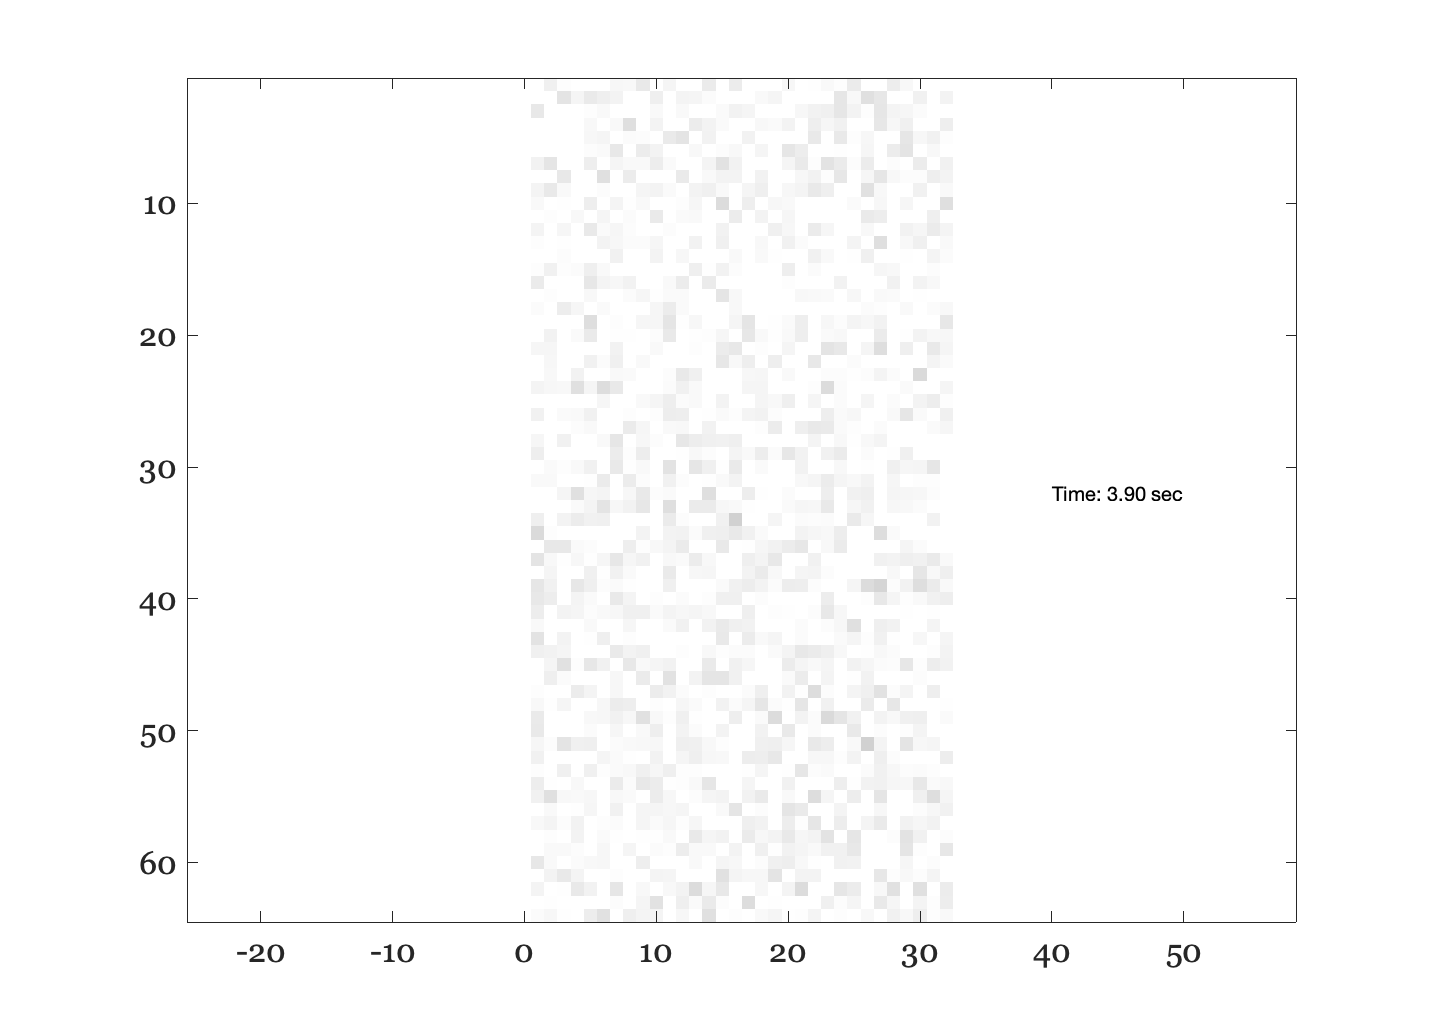

nSamples = 10000;
theta = zeros(nSamples,1);

% Then the position of the spins in the (x,y) plane will be
spins = [cos(theta), sin(theta)];

% And they will all fall at the same poisiton
figure;

plot(spins(:,1),spins(:,2),'o','LineWidth',3);
grid on; axis equal
set(gca,'xlim',[-2,2],'ylim',[-2 2])
grid on; xlabel('x'), ylabel('y')

% The total magnetization, summed across all the dipoles, is the vector
% length of the sum of these spins
averagePosition = sum(spins)/nSamples;         % Type v so you know what it is
netMagnetization = sqrt(averagePosition(1)^2 + averagePosition(2)^2);
fprintf('Net magnetization %f\n',netMagnetization);

Now, suppose that spins are precessing at slightly different rates. So after a few moments in time they do not fall at exactly the same angle. We can express this by creating a new vector theta that has some variability.

theta = rand(nSamples,1)*0.5;       % Uniform random number generator

% Here is the distribution of the angles
histogram(theta)
xlabel('Angle'), ylabel('Number of spins');
set(gca,'xlim',[0 2*pi])

Going through the same process we can make a plot of the spin positions

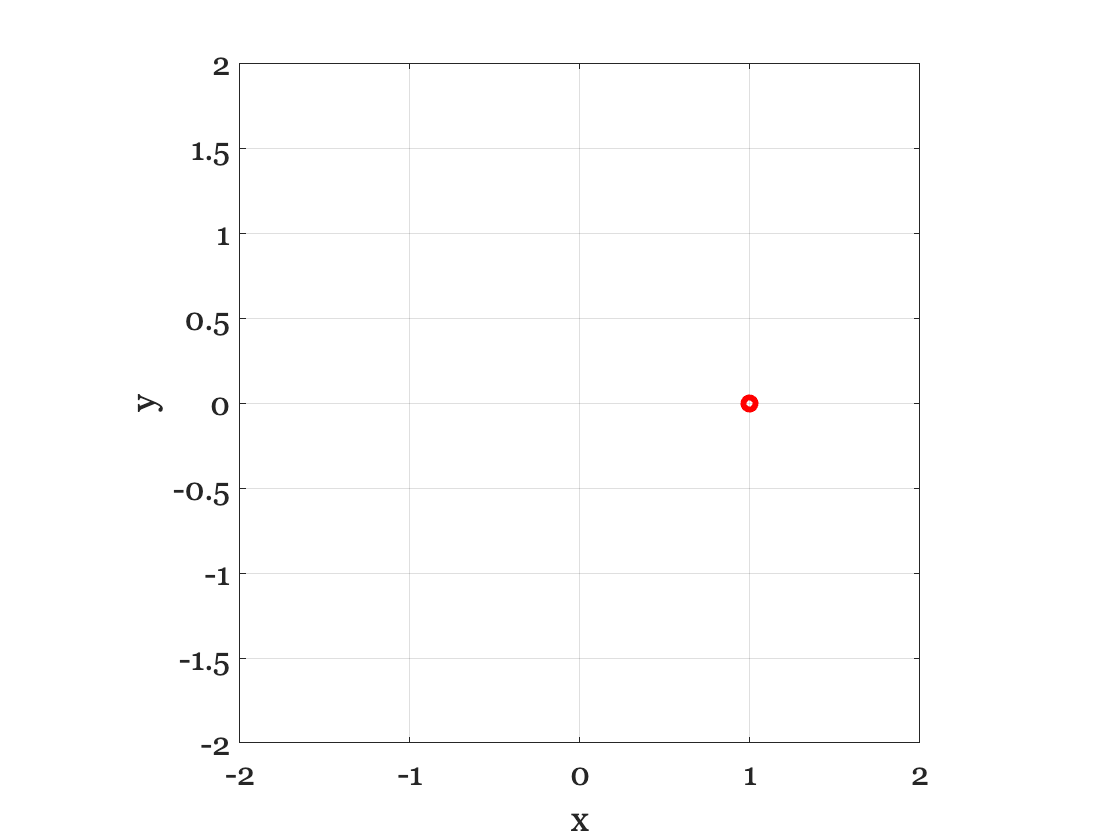

spins = [cos(theta), sin(theta)];
plot(spins(:,1),spins(:,2),'o');
grid on; axis equal
set(gca,'xlim',[-2,2],'ylim',[-2 2])
grid on; xlabel('x'), ylabel('y');


% Now, you can see that the net magnetization is somewhat smaller
averagePosition = mean(spins);
hold on;
plot(averagePosition(1),averagePosition(2),'k*','LineWidth',4);


Net magnetization 1.000000


netMagnetization = sqrt(averagePosition(1)^2 + averagePosition(2)^2);
fprintf('Net magnetization (0 deg) %f\n',netMagnetization);

If the spins grow even further out of phase, say they are spread over a full 2$\pi$ radians (180 deg).  In that case we have a bigger reduction in the net magnetization

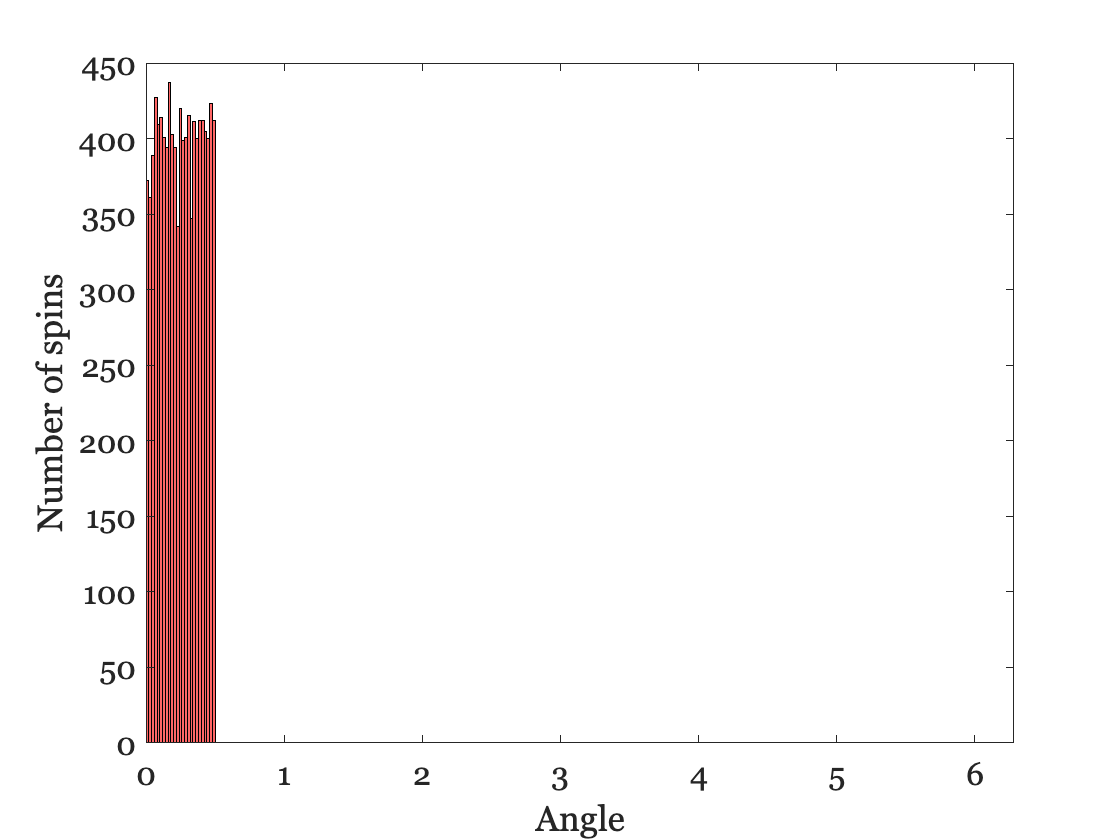

figure;
theta = rand(nSamples,1)*pi;
spins = [cos(theta), sin(theta)];
histogram(theta)
xlabel('Angle'), ylabel('Number of spins');
set(gca,'xlim',[0 2*pi])

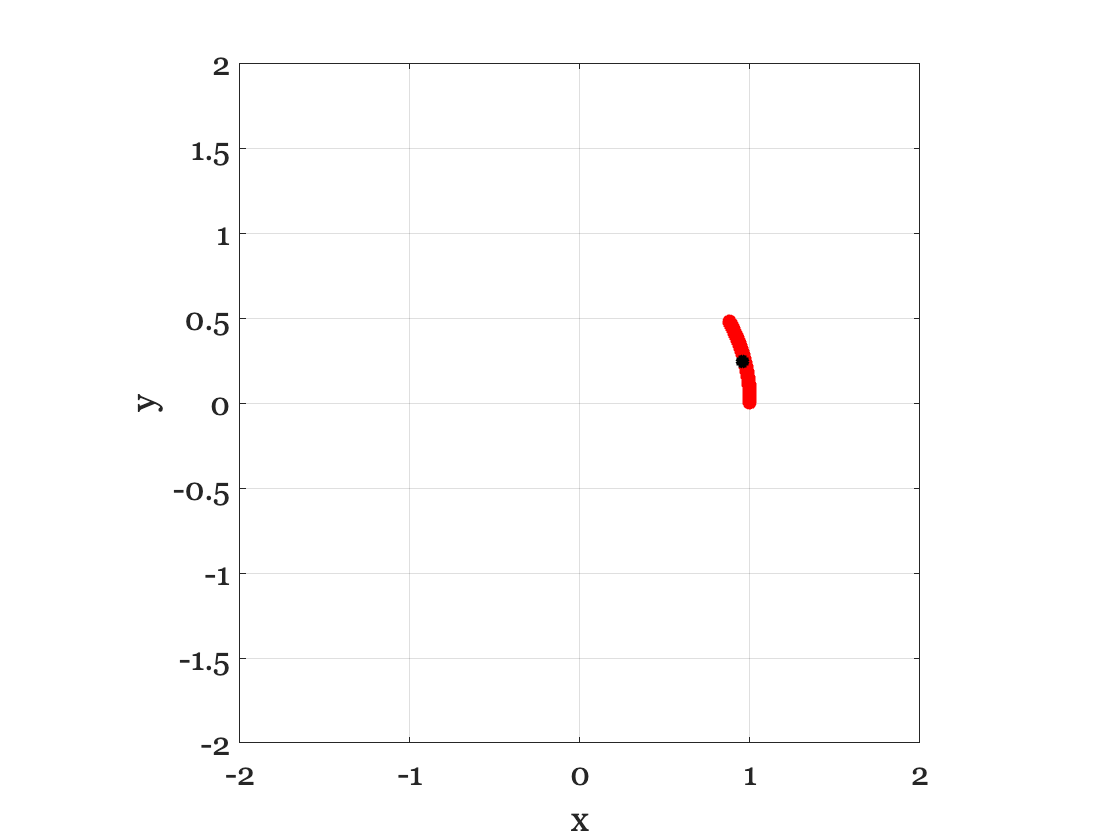

figure;
plot(spins(:,1),spins(:,2),'o');
grid on; axis equal
set(gca,'xlim',[-2,2],'ylim',[-2 2])
grid on; xlabel('x'), ylabel('y');

averagePosition = mean(spins);
hold on;
plot(averagePosition(1),averagePosition(2),'k*','LineWidth',4);


netMagnetization = sqrt(averagePosition(1)^2 + averagePosition(2)^2);
fprintf('Net magnetization (180deg) %f\n',netMagnetization);

**Bonus:** What do you expect the net magnetization to be when the spins are randomly distributed over 2 $\pi$ radians?

## Spin-dephasing (coherence)

In a typical experiment, the phases become less coherent (i.e., spread more) over time, decreasing the net transverse magnetization. The loss of signal from this **spin-dephasing** mechanism follows an exponential time constant. The rate depends on the spins' environment, say within gray or white matter.

figure;

Net magnetization (0 deg) 0.989621


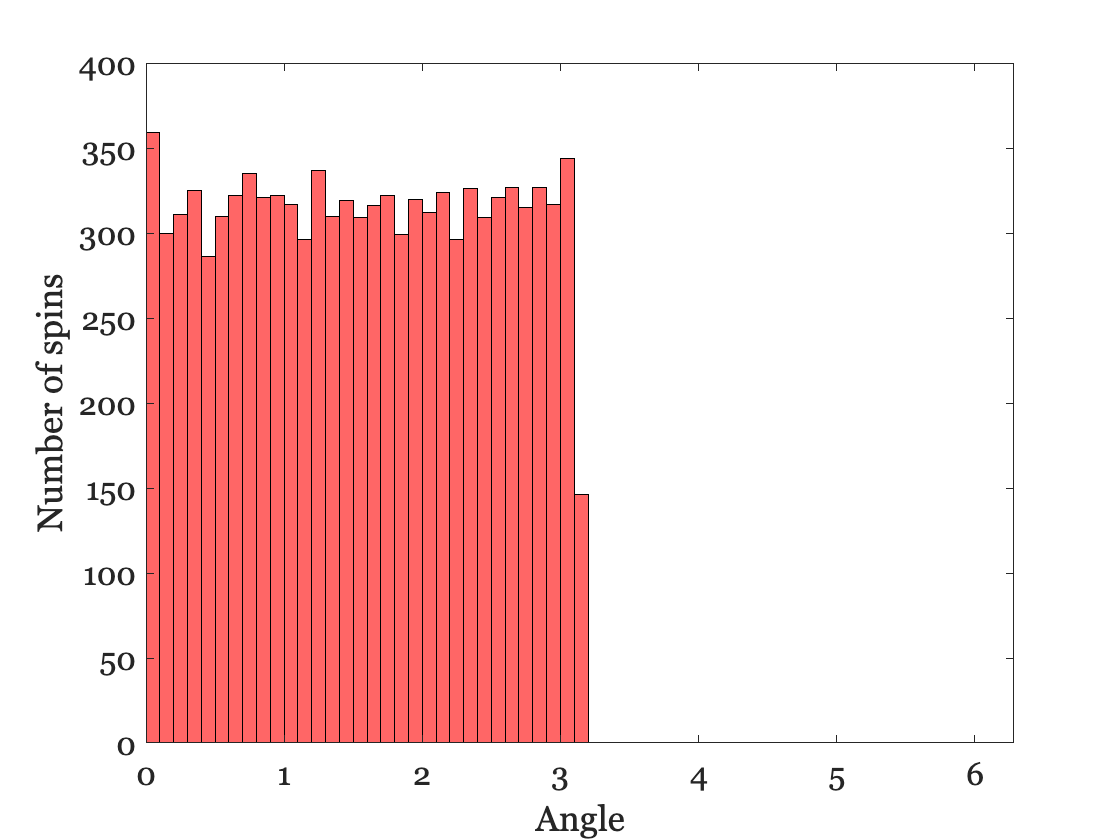

t = (0.01:0.01:0.3);% Time in secs
T2(1) = 0.08;       % T2 for white matter at 3T
T2(2) = 0.11;       % T2 for gray matter  at 3T
MzW = Mo*exp(-t/T2(1));
MzG = Mo*exp(-t/T2(2));
plot(t,MzG,'r--',t,MzW,'b-','LineWidth',3)
xlabel('Time (s)'); ylabel('Transverse magnetization (T2)'); 
grid on; legend('Gray','White')

## Experimental measurements of spin-lattice (T1) and spin-spin (T2) decay

T2 time constants are much shorter than T1 time constants. Comparison of T1 (spin-lattice) and T2 (spin-spin) decay constants at various B0 field strengths are:

                **Tissue**  | **T1** (1.5T,3.0T,4T)   |      **T2** (1.5T,3.0T,4T) (seconds)

                ---------------------------------------------------------------

                White     0.64, 0.86, 1.04       |     0.08, 0.08, 0.05

                Gray       0.88, 1.20, 1.40       |     0.08, 0.11 , 0.05

                ----------------------------------------------------------------

            **Source**: Jezzard and Clare Chapter 3 in the Oxford fMRI Book.  The numbers differ   somewhat between different publications (e.g.,  "[NMR relaxation times in the human brain at 3.0 tesla](https://pubmed.ncbi.nlm.nih.gov/10232510/)")

When we make T2-weighted images of the brain, remember that the differences in T2 provide the image contrast.  If we want to see the difference between gray and white matter, we want to make a measurement when the T2 signals differ. The largest T2 difference occurs at a  short time compared to the largest T1 difference.

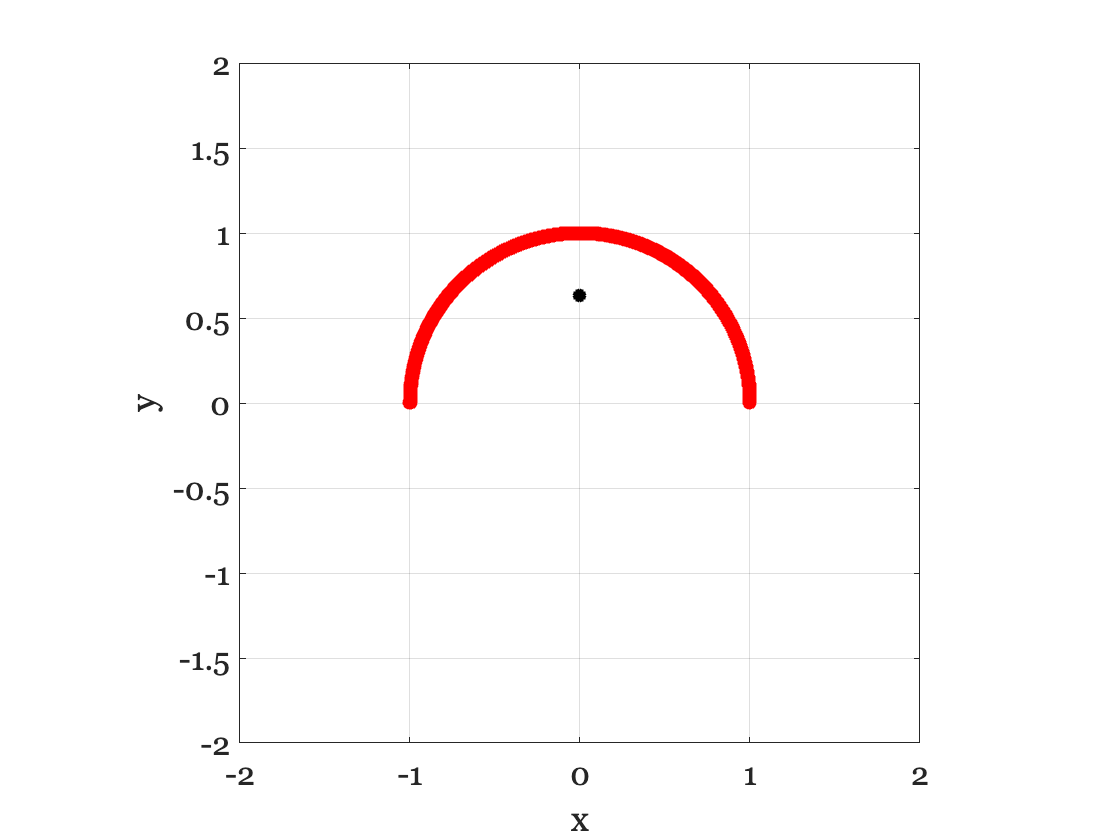

Net magnetization (180deg) 0.631969


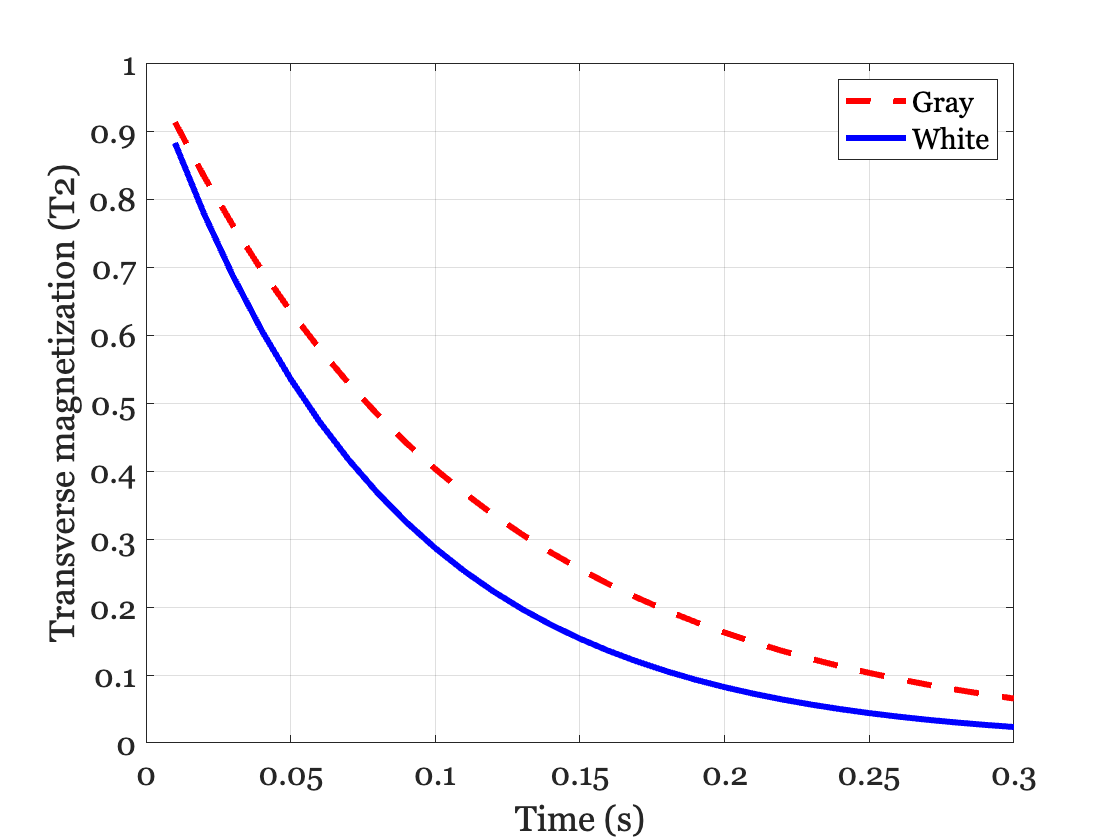

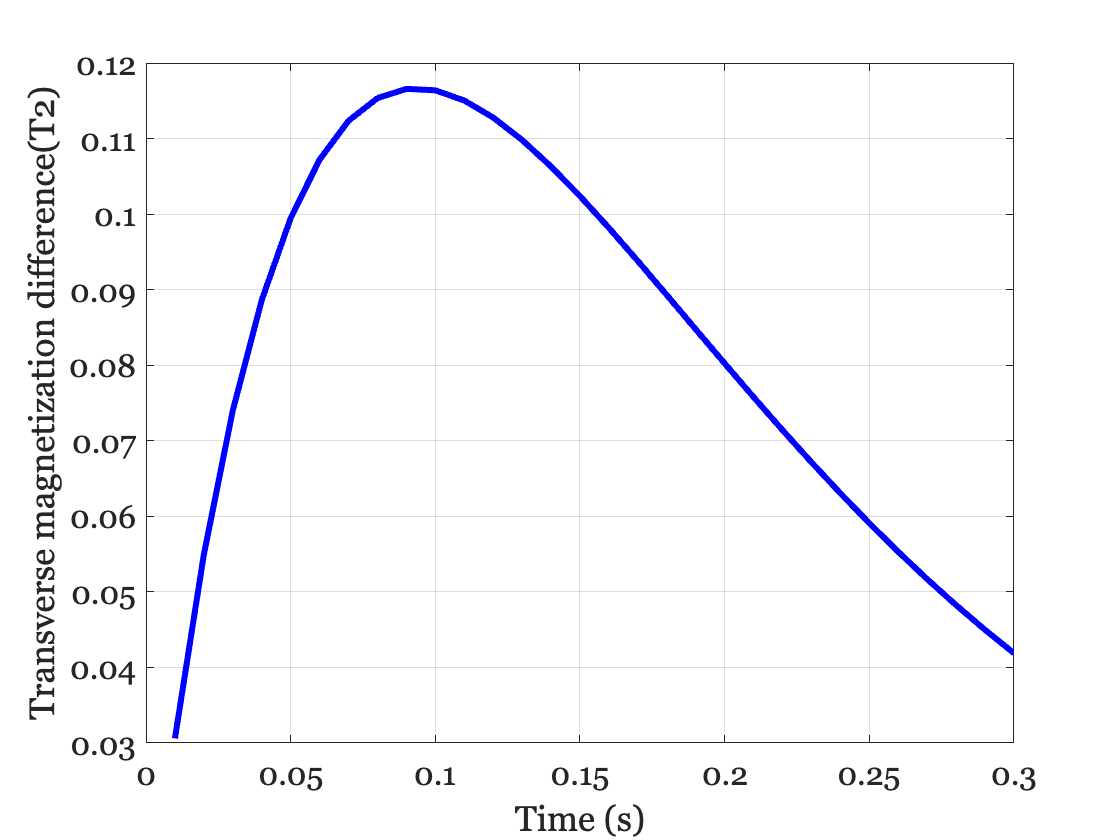

figure;
plot(t,abs(MzG - MzW),'b-','LineWidth',3)
xlabel('Time (s)'); ylabel('Transverse magnetization difference(T2)');
grid on

## Question 7

- Suppose you wanted to measure brain structure, and you were particularly interested in distinguishing gray matter from white matter (gray/white contrast). Based on the T1 and T2 curves we have calculated, would you choose to distinguish these two tissues using T1 or T2?  Why?

### Comments

- The best time to measure a T2 difference is short. Measurement of the T2 signal would be a problem were it not for the invention of an important measurement method called 'Spin Echo'. We will begin the next tutorial by explaining that idea.

- There are many essential imaging ideas that we have not yet explored. For example, how can we measure T1 and T2 separately? 

- Perhaps most importantly, to this point we are only measuring the bulk signals.  An important question is this: How can we form an image that measures T1 or T2 at many different points? These are the topics we will take up in the following tutorials.